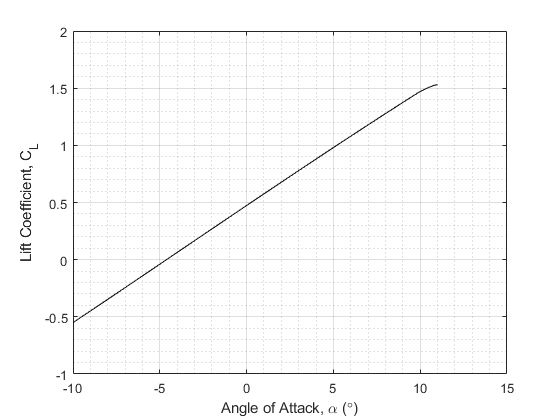

CDo = 0.0253;

CLCDMax = 0;

for i = 1:211    %353 %For Flaps
    
    %AoA(i) = -21.1+i*0.1; %For Flaps
    
    AoA(i) = -10.1+i*0.1;
    
    [CL(i),CD(i)] = Vanguard_VLM(AoA(i));
    
    if CL(i)/(CD(i)+CDo) > CLCDMax
        
        CLCDMax = CL(i)/(CD(i)+CDo);
        
    end
    
end

figure
plot(AoA,CL, 'black')
grid on
grid minor
xlabel('Angle of Attack, \alpha ({\circ})')
ylabel('Lift Coefficient, C_L')

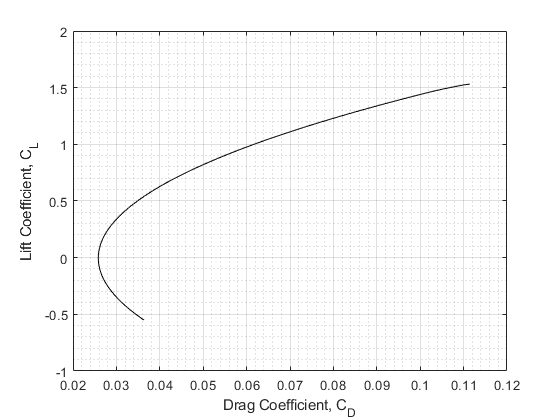


figure
plot(CD+CDo,CL, 'black')
grid on
grid minor
xlabel('Drag Coefficient, C_D')
ylabel('Lift Coefficient, C_L')